This combines all 4 of our live script versions of our code into a single mlx live script. This also makes it easier to export to a PDF.

# Question 1: Jaxen White

% Dummy Variable. Added by Ryan.
% Sets up a flag that allows Q4.m to end this script before the plots are
% made.
Q4_flag(2) = 0;

% Parameters
T = 100; % Total simulation time (days)
h = 1; % Time step (days)
N = 1000; % Total population (constant)
S0 = 990; % Initial susceptible population
I0 = 10; % Initial infected population
R0 = 0; % Initial recovered population

% Parameter sets for different diseases
parameters = [
    0.3, 0.1;  % Seasonal Influenza (β, γ)
    1.0, 0.1;  % COVID-19 (β, γ)
    2.0, 0.2   % Measles (β, γ)
            ];
disease_names = {'Seasonal Influenza', 'COVID-19', 'Measles'};

for k = 1:size(parameters, 1)
    beta = parameters(k, 1);
    gamma = parameters(k, 2);

    S = zeros(1, T+1); I = zeros(1, T+1); R = zeros(1, T+1);
    S(1) = S0; I(1) = I0; R(1) = R0;

    % RK4 method
    for t = 1:T
        % Current values
        S_t = S(t); I_t = I(t); R_t = R(t);

        % Define ODEs
        dS = @(S, I) -(beta / N) * S * I;
        dI = @(S, I) (beta / N) * S * I - gamma * I;
        dR = @(I) gamma * I;

        % RK4 coefficients
        k1_S = h * dS(S_t, I_t);
        k1_I = h * dI(S_t, I_t);
        k1_R = h * dR(I_t);

        k2_S = h * dS(S_t + k1_S/2, I_t + k1_I/2);
        k2_I = h * dI(S_t + k1_S/2, I_t + k1_I/2);
        k2_R = h * dR(I_t + k1_I/2);

        k3_S = h * dS(S_t + k2_S/2, I_t + k2_I/2);
        k3_I = h * dI(S_t + k2_S/2, I_t + k2_I/2);
        k3_R = h * dR(I_t + k2_I/2);

        k4_S = h * dS(S_t + k3_S, I_t + k3_I);
        k4_I = h * dI(S_t + k3_S, I_t + k3_I);
        k4_R = h * dR(I_t + k3_I);
        
        S(t+1) = S_t + (k1_S + 2*k2_S + 2*k3_S + k4_S) / 6;
        I(t+1) = I_t + (k1_I + 2*k2_I + 2*k3_I + k4_I) / 6;
        R(t+1) = R_t + (k1_R + 2*k2_R + 2*k3_R + k4_R) / 6;
    end

% This was added by Ryan. This makes it so that Q4.m can run this script
% without also importing/displaying any plots/figures.
if Q4_flag(1) == 1
    return
end

    % Plot results
    figure;
    hold on;
    plot(0:T, S, 'b', 'LineWidth', 1.5);
    plot(0:T, I, 'r', 'LineWidth', 1.5);
    plot(0:T, R, 'g', 'LineWidth', 1.5);
    title(['SIR Model: ', disease_names{k}]);
    xlabel('Time (days)');
    ylabel('Population');
    legend('Susceptible', 'Infected', 'Recovered');
    grid on;
    hold off;
end

A higher transmission rate such as, Measles with beta=2 causes a rapid increase in infections, leading to a sharp peak in I(t). This makes the disease spread quickly through the susceptible population, depleting S(t) rapidly. A lower recovery rate prolongs the duration of infection, keeping I elevated for longer periods like COVID-19 with Gamma=0.1 Diseases with higher beta/gamma ratios, the basic reproduction number R_0, spread more aggressively and involve larger portions of the population before fading. In conclusion, the measles virus spreads quickly due to its high beta, but it has a fast recovery so it limits its time of infection. Covid-19 has a slower spread but a longer infection period which reflects its beta=1 and gamma=0.1. The seasonal Influenza has a moderate gamma and beta so it is slower and less dramatic all around.

clear;

# Question 2: Cyal Sam

%%%% 100
% Parameters
T = 100; % Total simulation time (days)
h = 1; % Time step (days)
N = 1000; % Total population (constant)
S0 = 990; % Initial susceptible population
I0 = 10; % Initial infected population
R0 = 0; % Initial recovered population
% Parameter sets for different diseases
parameters = [
    0.3, 0.1  % Seasonal Influenza (β, γ)
             ];
for k = 1:size(parameters, 1)
    beta = parameters(k, 1);
    gamma = parameters(k, 2);
    S = zeros(1, T+1);
    I = zeros(1, T+1);
    R = zeros(1, T+1);
    S(1) = S0;
    I(1) = I0;
    R(1) = R0;
    % RK4 method
    for t = 1:T
        % Current values
        S_t = S(t); I_t = I(t); R_t = R(t);
        % Define ODEs
        dS = @(S, I) -(beta / N) * S * I;
        dI = @(S, I) (beta / N) * S * I - gamma * I;
        dR = @(I) gamma * I;
        % RK4 coefficients
        k1_S = h * dS(S_t, I_t);
        k1_I = h * dI(S_t, I_t);
        k1_R = h * dR(I_t);
        k2_S = h * dS(S_t + k1_S/2, I_t + k1_I/2);
        k2_I = h * dI(S_t + k1_S/2, I_t + k1_I/2);
        k2_R = h * dR(I_t + k1_I/2);
        k3_S = h * dS(S_t + k2_S/2, I_t + k2_I/2);
        k3_I = h * dI(S_t + k2_S/2, I_t + k2_I/2);
        k3_R = h * dR(I_t + k2_I/2);
        k4_S = h * dS(S_t + k3_S, I_t + k3_I);
        k4_I = h * dI(S_t + k3_S, I_t + k3_I);
        k4_R = h * dR(I_t + k3_I);
        S(t+1) = S_t + (k1_S + 2*k2_S + 2*k3_S + k4_S) / 6;
        I(t+1) = I_t + (k1_I + 2*k2_I + 2*k3_I + k4_I) / 6;
        R(t+1) = R_t + (k1_R + 2*k2_R + 2*k3_R + k4_R) / 6;
    end
end
h2 = 2;
t2 = 0 : h2 : 100;
%%%% This is the second part that is to interpolate the odd values that
%%%% is to be found using the Linear Newton form then using the Quadratic
%%%% Lagrange form
for z = 1 : length(t2) - 1
    SNI(z+1) = S(z) + ((S(z+1) - S(z)) / ((z+1) - (z))) * ((z+1) - (z));
    INI(z+1) = I(z) + ((I(z+1) - I(z)) / ((z+1) - (z))) * ((z+1) - (z));
    RNI(z+1) = R(z) + ((R(z+1) - R(z)) / ((z+1) - (z))) * ((z+1) - (z));
    %%%% The Quadratic Lagrange Method Form
    for j = 1 : z
        X_1(j+1) = (((j+1) - (j)) * ((j+1) - (j+3))) / ((((j) - (j+1)) * ((j) + (j+3))));
        X_2(j+1) = (((j+1) - (j)) * ((j+1) - (j+3))) / (((j+1) - (j)) * ((j+1) - (j+3)));
        X_3(j+1) = (((j+1) - (j)) * ((j+1) - (j+2))) / (((j+3) - (j)) * ((j+3) - (j+2)));
        QS(j+1) = (X_1(j) * S(j)) + (X_2(j+1) * S(j+2)) + (X_3(j+1) * S(j+3));
        QI(j+1) = (X_1(j) * I(j)) + (X_2(j+1) * I(j+2)) + (X_3(j+1) * I(j+3));
        QR(j+1) = (X_1(j) * R(j)) + (X_2(j+1) * R(j+2)) + (X_3(j+1) * R(j+3));
    end
end
L2_s = sqrt((S(z+1) - SNI(z+1)/ T)); 
L2_i = sqrt((I(z+1) - INI(z+1)/ T)); 
L2_r = sqrt((R(z+1) - RNI(z+1)/ T)); 
L2_Qs = sqrt((QS(z+1) - SNI(z+1)/ T)); 
L2_Qi = sqrt((QI(z+1) - INI(z+1)/ T)); 
L2_Qr = sqrt((QR(z+1) - RNI(z+1)/ T)); 
%%%% The Errors computed from the above formulas in 2x3 matrix print
fprintf('L2 Error Table:\n');
fprintf('               S(t)         I(t)         R(t)\n');
fprintf('Linear    : %.7f    %.7f    %.7f\n', L2_s, L2_i, L2_r);
fprintf('Quadratic : %.7f    %.7f    %.7f\n', L2_Qs, L2_Qi, L2_Qr);

The values that are more accurate are the Quadratic portion due to the difference in the values being greater compared to the linear value. The linear values error are larger than the quadratic meaning that the quadratic is the one to produce less errors.

clear;

# Question 3: Kyle Swirski

% Group Project Part 3: Least-Squares Regression.
% Initial Conditions and Necessary Equations for Step 1.
S(1) = 990;                     % Initial susceptible population.
I(1) = 10;                      % Initial infected population.
R(1) = 0;                       % Initial recovered population.
N = 1000;                       % Total population.
B = 0.3;                        % Transmition rate.
Y = 0.1;                        % Recovery rate.
h = 1;                          % Time step.
t = 0:h:30;                     % Simulation duration.
dS = @(S,I)(-B*S*I/N);          % Given ODE for S(t).
dI = @(S,I)((B*S*I/N)-(Y*I));   % Given ODE for I(t).
dR = @(I)(Y*I);                 % Given ODE for R(t).
% Loop that determines the values of S(t), I(t), and R(t) using the given
% initial values and the fourth-order Runge-Kutta Method for each day.
for x = 1:(length(t)-1)
    K1S = dS(S(x),I(x));
    K1I = dI(S(x),I(x));
    K1R = dR(I(x));
    K2S = dS(S(x)+(h/2),I(x)+(K1I*h/2));
    K2I = dI(S(x)+(h/2),I(x)+(K1I*h/2));
    K2R = dR(I(x)+(K1I*h/2));
    K3S = dS(S(x)+(h/2),I(x)+(K2I*h/2));
    K3I = dI(S(x)+(h/2),I(x)+(K2I*h/2));
    K3R = dR(I(x)+(K2I*h/2));
    K4S = dS(S(x)+h,I(x)+(K3I*h));
    K4I = dI(S(x)+h,I(x)+(K3I*h));
    K4R = dR(I(x)+(K3I*h));
    S(x+1) = S(x)+((K1S+(2*K2S)+(2*K3S)+K4S)*h/6);
    I(x+1) = I(x)+((K1I+(2*K2I)+(2*K3I)+K4I)*h/6);
    R(x+1) = R(x)+((K1R+(2*K2R)+(2*K3R)+K4R)*h/6);
end
% Plots the values of S(t), I(t), and R(t) determined in the loop above.
figure(1)
plot(t,S,'b',t,I,'r',t,R,'g')
xlabel('Time (Days)')
ylabel('Population (People)')
title('SIR Model Dynamics')
legend('Susceptible','Infected','Recovered')
% Initial Conditions and Necessary Equations for Step 2.
n = length(t);
u = sum(t);
w = sum(t.^2);
lnI = log(I);
y = sum(lnI);
z = sum(t.*lnI);
k = ((n*z)-(u*y))/((n*w)-(u^2));
lnI0 = (y-(k*u))/n;
I0 = exp(lnI0);
B1 = ((k+Y)*N)/S(1);
% Plots the analytical solution, I(t) = I(0)e^kt, over 30 days.
figure(2)
plot(t,lnI,'r',t,lnI0+(k*t),'b')
xlabel('Time (Days)')
ylabel('ln(I(t))')
title('Least Squares Fit for ln(I(t)) over 30 Days')
legend('Data ln(I(t))','Linear Fit')
% Displays the estimated values for I(0), k, and beta over 30 days.
disp("Requested information for Step 2.")
disp("Estimated I(0) over 30 Days: " + I0)
disp("Estimated k over 30 Days: " + k)
disp("Estimated beta over 30 Days: " + B1)
% Initial Conditions and Necessary Equations for Step 3.
d = t(1:11);
m = length(d);
b = sum(d);
c = sum(d.^2);
J = I(1:11);
lnJ = log(J);
e = sum(lnJ);
f = sum(d.*lnJ);
l = ((m*f)-(b*e))/((m*c)-(b^2));
lnJ0 = (e-(l*b))/m;
J0 = exp(lnJ0);
B2 = ((l+Y)*N)/S(1);
% Plots the analytical solution, I(t) = I(0)e^(kt), over 10 days.
figure(3)
plot(d,lnJ,'r',d,lnJ0+(l*d),'b')
xlabel('Time (Days)')
ylabel('ln(I(t))')
title('Least Squares Fit for ln(I(t)) over 10 Days')
legend('Data ln(I(t))','Linear Fit')
% Displays the estimated values of I(0), k, and beta over 10 days.
disp("Requested information for Step 3.")
disp("Estimated I(0) over 10 Days: " + J0)
disp("Estimated k over 10 Days: " + l)
disp("Estimated beta over 10 Days: " + B2)

As can be seen from the graphs of lnI(t) and the estimated values of I(0), k, and beta, reducing the number of days to 10 results in a significant increase in the accuracy of said values. By using fewer sets of data, the model becomes more linear, meaning a line can be fit to the data much more accurately compared to using more data points. Hence the values of I(t), k, and beta being much more accurate with 10 days of data instead of the full 30 days of data.

clear;

# Question 4: Ryan Smith

Q4_flag(1) = 1; Q1;
% This runs the script for Q1 without importing any of the plots made in
% the script.

% New Parameters
B0 = 0.3;                       % Initial transmission rate
A = 5;                          % Amplitude
w = (2*pi*365) / 365;           % Angular frequency

% Edited Parameters
T = 30;                         % Total simulation time (days)
h = 0.1;                        % Time step (days)
t_vec = linspace(0,30,30/h+1);  % Time vector for easier plotting

B = @(t) B0*(1 + A*sin(w*t));     % Transmission rate variation
gamma = 0.1;                    % New gamma value

% SIR model with β(t)

% RK4 method
    for t = 1:300
        % Current values
        S_t = S(t); I_t = I(t); R_t = R(t);
        beta = B(t/10);

        % Define ODEs
        dS = @(S, I) -(beta / N) * S * I;
        dI = @(S, I) (beta / N) * S * I - gamma * I;
        dR = @(I) gamma * I;

        % RK4 coefficients
        k1_S = h * dS(S_t, I_t);
        k1_I = h * dI(S_t, I_t);
        k1_R = h * dR(I_t);

        k2_S = h * dS(S_t + k1_S/2, I_t + k1_I/2);
        k2_I = h * dI(S_t + k1_S/2, I_t + k1_I/2);
        k2_R = h * dR(I_t + k1_I/2);

        k3_S = h * dS(S_t + k2_S/2, I_t + k2_I/2);
        k3_I = h * dI(S_t + k2_S/2, I_t + k2_I/2);
        k3_R = h * dR(I_t + k2_I/2);

        k4_S = h * dS(S_t + k3_S, I_t + k3_I);
        k4_I = h * dI(S_t + k3_S, I_t + k3_I);
        k4_R = h * dR(I_t + k3_I);
        
        S(t+1) = S_t + (k1_S + 2*k2_S + 2*k3_S + k4_S) / 6;
        I(t+1) = I_t + (k1_I + 2*k2_I + 2*k3_I + k4_I) / 6;
        R(t+1) = R_t + (k1_R + 2*k2_R + 2*k3_R + k4_R) / 6;
    end
plot(t_vec, S, t_vec, I, t_vec, R)
xlabel('Time (days)'); ylabel('Population');
legend('Susceptible', 'Infected', 'Recovered');
title('SIR Model: Periodic Variation');

The recovery rate doesn't seem to oscilate at all, but the susceptibility and infection rates definitely have some oscilating happening.

fft_I = fft(I);
Fs = 1/T;
samples = 300;
f_vec = Fs * (0:(samples/2));
P_I = abs(fft_I/samples);
F_I = P_I(1:samples/2+1);
F_I(2:end-1) = 2 * F_I(2:end-1);
plot(f_vec, F_I)
xlabel('Frequency (Hz)'); ylabel('Amplitude');
title('Infection Spectrum for Periodic Variation');

This looks like a logarithmic graph with a blip at 1 Hz. This makes sense.


% Edited parameters
w = (2*pi*100) / 365;           % Angular frequency
B = @(t) B0*(1 + A*sin(w*t));     % Transmission rate variation

% RK4 method
    for t = 1:300
        % Current values
        S_t = S(t); I_t = I(t); R_t = R(t);
        beta = B(t/10);

        % Define ODEs
        dS = @(S, I) -(beta / N) * S * I;
        dI = @(S, I) (beta / N) * S * I - gamma * I;
        dR = @(I) gamma * I;

        % RK4 coefficients
        k1_S = h * dS(S_t, I_t);
        k1_I = h * dI(S_t, I_t);
        k1_R = h * dR(I_t);

        k2_S = h * dS(S_t + k1_S/2, I_t + k1_I/2);
        k2_I = h * dI(S_t + k1_S/2, I_t + k1_I/2);
        k2_R = h * dR(I_t + k1_I/2);

        k3_S = h * dS(S_t + k2_S/2, I_t + k2_I/2);
        k3_I = h * dI(S_t + k2_S/2, I_t + k2_I/2);
        k3_R = h * dR(I_t + k2_I/2);

        k4_S = h * dS(S_t + k3_S, I_t + k3_I);
        k4_I = h * dI(S_t + k3_S, I_t + k3_I);
        k4_R = h * dR(I_t + k3_I);
        
        S(t+1) = S_t + (k1_S + 2*k2_S + 2*k3_S + k4_S) / 6;
        I(t+1) = I_t + (k1_I + 2*k2_I + 2*k3_I + k4_I) / 6;
        R(t+1) = R_t + (k1_R + 2*k2_R + 2*k3_R + k4_R) / 6;
    end
plot(t_vec, S, t_vec, I, t_vec, R)
xlabel('Time (days)'); ylabel('Population');
legend('Susceptible', 'Infected', 'Recovered');
title('SIR Model: Periodic Variation');
fft_I = fft(I);
Fs = 1/T;
samples = 300;
f_vec = Fs * (0:(samples/2));
P_I = abs(fft_I/samples);
F_I = P_I(1:samples/2+1);
F_I(2:end-1) = 2 * F_I(2:end-1);
plot(f_vec, F_I)
xlabel('Frequency (Hz)'); ylabel('Amplitude');
title('Infection Spectrum for Periodic Variation');

The peak frequency shift to smaller values, but there are now two possible max frequency peaks. This definitely matches what happened to the SIR graph as the wavelengths increased a lot, which does inversely impact frequency, so it makes sense that the peak frequency would decrease. Also, all of the graphs in the SIR now have minor oscilations.

# GitHub Stuff

Link: [https://github.com/GenericNR/MAE384-Project/tree/main](https://github.com/GenericNR/MAE384-Project/tree/main)

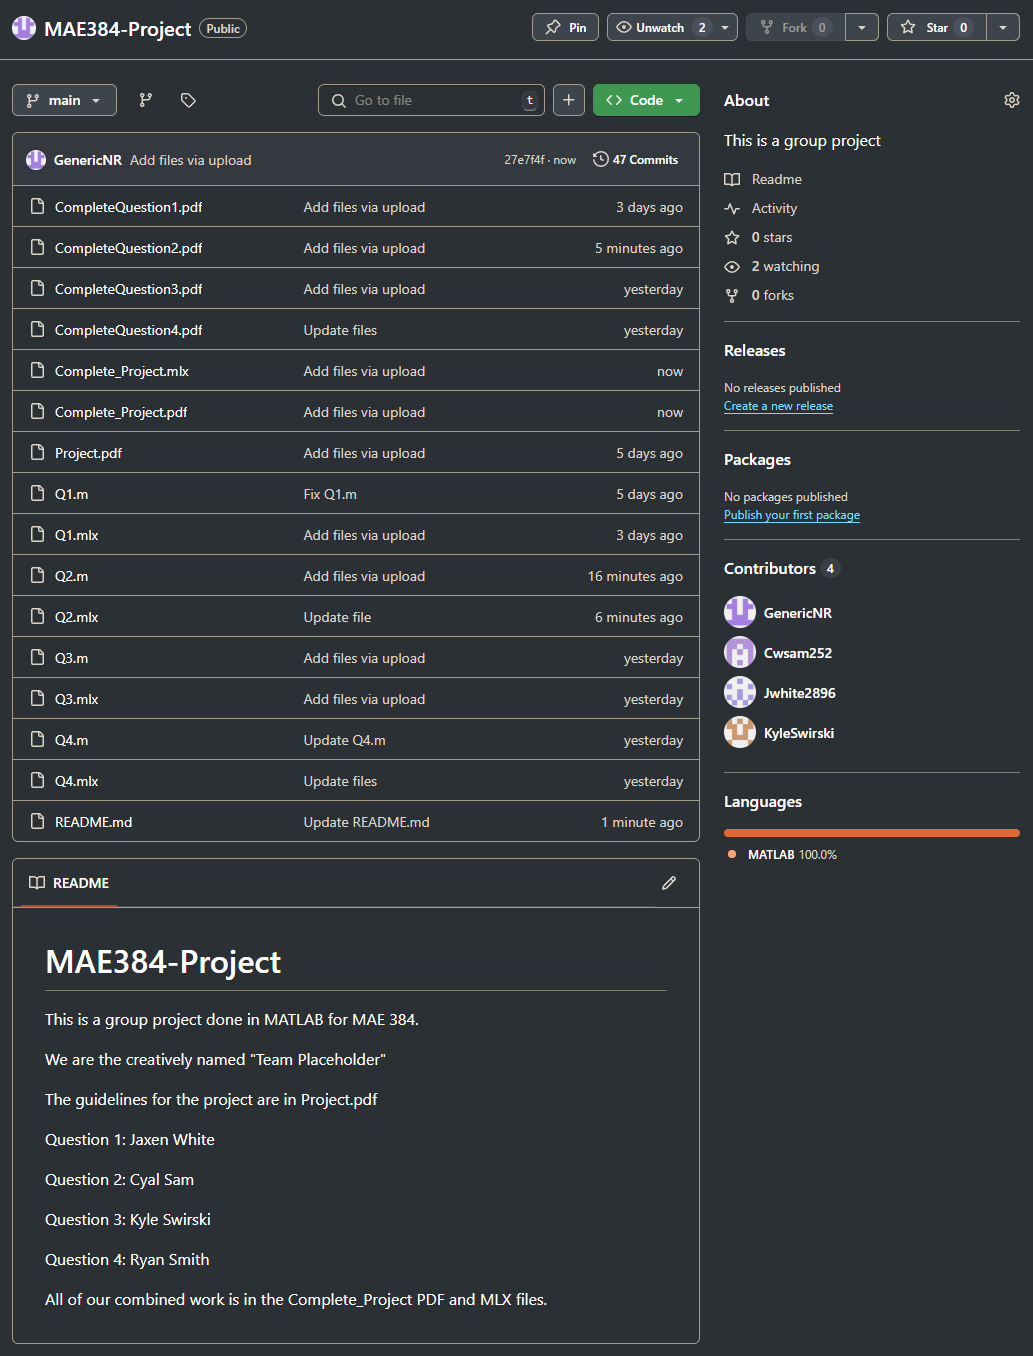

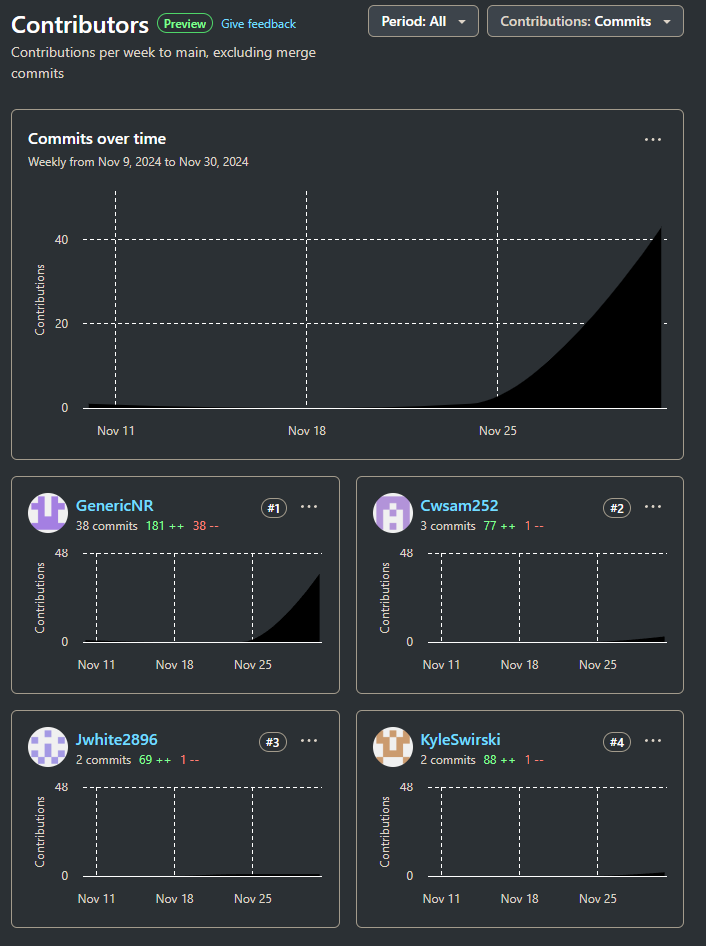

Ryan Smith was the group leader, hence why he has by far the most commits.